# Set data

obj = importdata('forclass.mat');
img_original = obj;
y = (1:size(obj,1))-size(obj,1)/2; % image height
x = (1:size(obj,2))-size(obj,2)/2; % image width
[X,Y] = meshgrid(x,y);


## Setup PSF

gaussian = @(x,y,c) exp(-((x.^2)+(y.^2))./(2*c.^2));
c = [1, 1.5, 2, 2.5];

psf = ones(size(obj,1),size(obj,2),length(c));
for ii = 1:length(c)
    psf(:,:,ii) = gaussian(X,Y,c(ii));
end

## Setup OTF

OTF = ifftshift(fft2(fftshift(psf)));
% The optical transfer function (OTF) is defined as the Fourier transform
% of the point spread function.

## Object goes through the system

OBJ = ifftshift(fft2(fftshift(obj)));
IMG = OBJ.*OTF;

img = ifftshift(ifft2(fftshift(IMG)));

## Add Noise to the system

noisyImg = img + rand(size(img))*500;

## Input Image

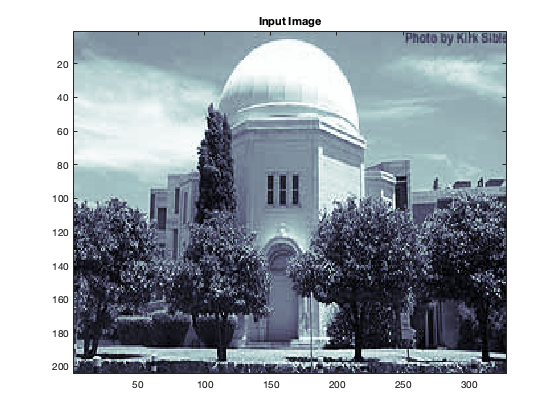

figure()
imagesc(img_original)
colormap bone
title("Input Image")

## Output Image

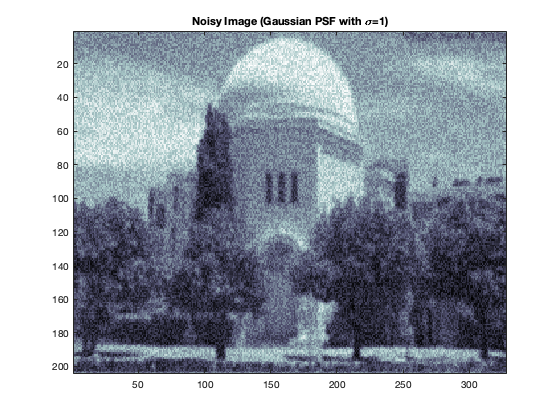

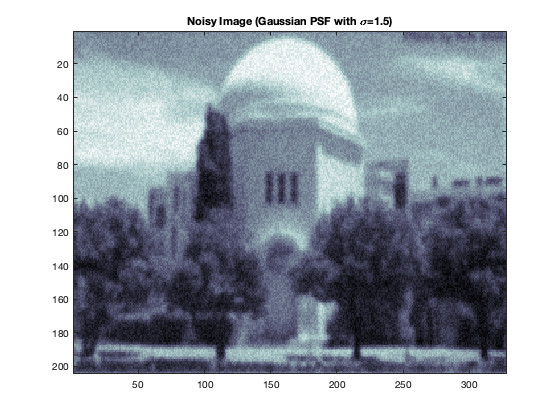

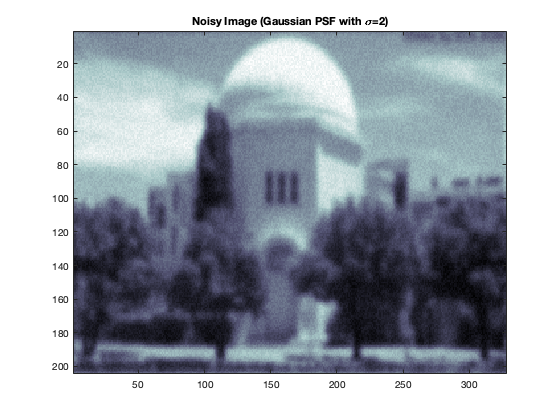

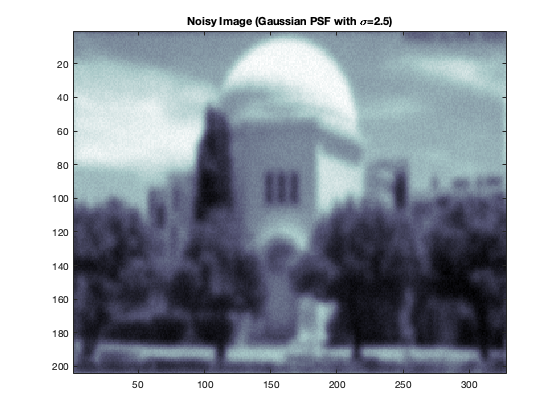

for ii = 1:length(c)
    figure()
    imagesc(real(noisyImg(:,:,ii)))
    colormap bone
    title(['Noisy Image (Gaussian PSF with \sigma=' num2str(c(ii)) ')'])
end

## Deconvolve Image

NOISYIMG = ifftshift(fft2(fftshift(noisyImg)));
NOISYOBJ = NOISYIMG./OTF;
noisyObj = ifftshift(ifft2(fftshift(NOISYOBJ)));

## Output Noisy Image

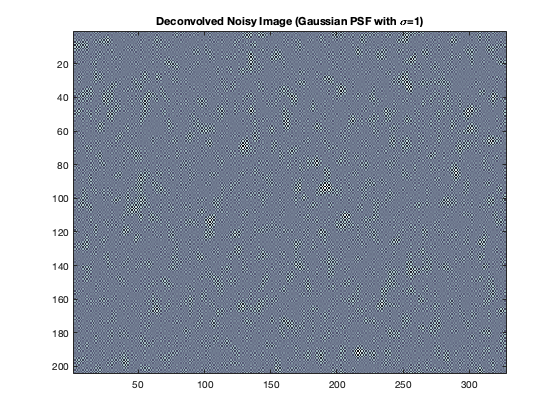

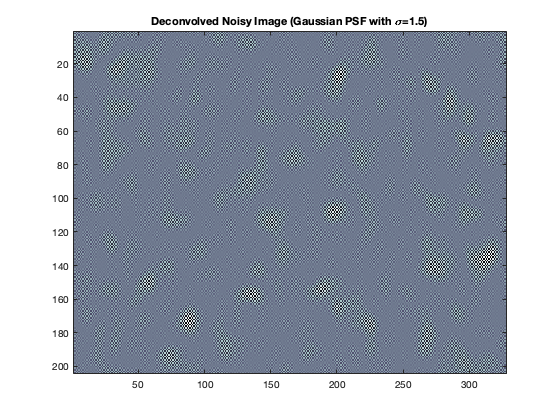

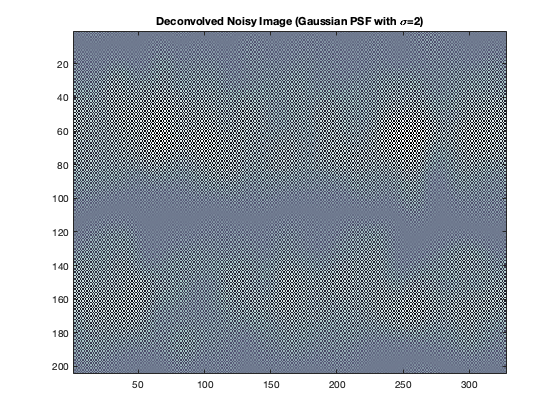

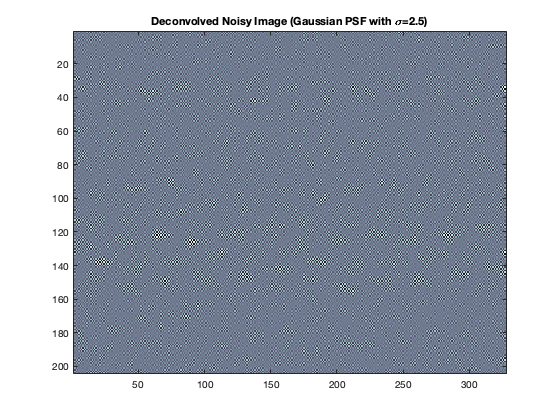

for ii = 1:length(c)
    figure()
    imagesc(real(noisyObj(:,:,ii)))
    colormap bone
    title(['Deconvolved Noisy Image (Gaussian PSF with \sigma=' num2str(c(ii)) ')'])
end